# GPFOR

Uses a FOR-loop to find multiple linear fits.

See also: GPIF

## Load data

load gPrices

## Choose a country

Enter a country name without capitalization to see the effect of the warning.

myctry = inputdlg('Enter a country: ');
myctry = myctry{1};
idx = strcmpi(myctry,country);

## Check to see if data exists before finding fit

Australia:Germany slope: 0.55907


Canada:Germany slope: 0.5159


France:Germany slope: 0.80409


Germany:Germany slope: 1


Italy:Germany slope: 0.74022


Japan:Germany slope: 0.3799


Mexico:Germany slope: 0.2338


South Korea:Germany slope: 0.78602


UK:Germany slope: 0.95646


USA:Germany slope: 0.44908


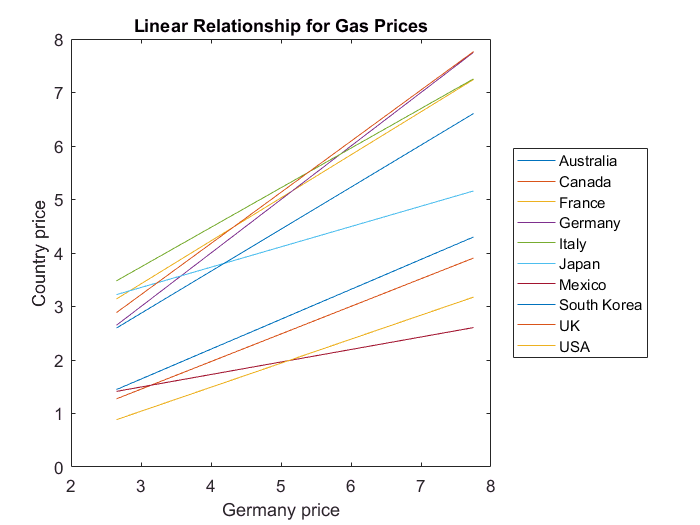

if any(idx)  % Data exists?
    % Extract data for the chosen country
    myPrices = Prices(:,idx);
    % Check for proper capitalization of country name
    if ~strcmp(myctry,country{idx})
        warning(['Entered ',myctry,'. Modified to ',country{idx},'.'])
        myctry = country{idx};
    end
    % Loop over all countries
    for k = 1:length(country)
        % Find the linear fit of each country versus chosen country
        c = polyfit(myPrices,Prices(:,k),1);
        disp([country{k},':',myctry,' slope: ',num2str(c(1))])
        linfits(:,k) = myPrices*c(1) + c(2);
    end
    plot(myPrices,linfits)
    title('Linear Fit between Country Gas Prices')
    xlabel([myctry,' price'])
    ylabel('Country price')
    legend(country,'location','eastoutside')
else
    % No data -- error!
    error(['No data for ',myctry,'.'])
end